clc, clear all, close all

#### Vstupni hodnoty

Bez symbolickych promennych 

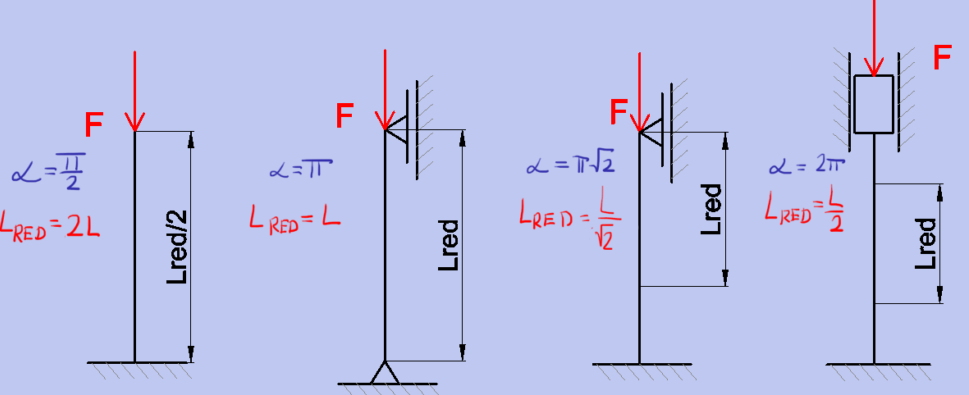

Shrnuti Radek Zeman:

[https://onlineschool.cz/pruznost-pevnost/vzperna-stabilita-prutu/](https://onlineschool.cz/pruznost-pevnost/vzperna-stabilita-prutu/)

Vypocet kvadr. momentu:

[https://e-konstrukter.cz/technicke-vypocty/14-kvadraticky-moment-a-modul-prurezu-v-ohybu](https://e-konstrukter.cz/technicke-vypocty/14-kvadraticky-moment-a-modul-prurezu-v-ohybu)

% Stanovit z obrazku 
alpha = pi;

L = 2; % [m] delka prutu

F = 100000; % Zatezujici sila

E = 200e9;
Sigma_k = 250e6;

D = 0.08;

#### Vypocet 

% Kvadr moment k te ose, kde je nejmensi
J_min = 2.0106193e-6;

% Obsah prurezu
S = (pi*D^2)/4; 

% Stihlost 
lambda = L/(sqrt(J_min/S))

lambda = 100.0000


% Kriticka stihlost 
lambda_k = alpha*sqrt(E/Sigma_k)

lambda_k = 88.8577


% Kriticka sila --> Pouze pokud lambda > lambda k, jinak klasicky mez kluzu
if lambda > lambda_k
    F_kr = ((alpha^2)*E*J_min)/(L^2)
else
    sprintf('Treba resit k meznimu stavu pruznosti')
end

F_kr = 9.9220e+05



% Bezpecnost 
kv = F_kr/F

kv = 9.9220